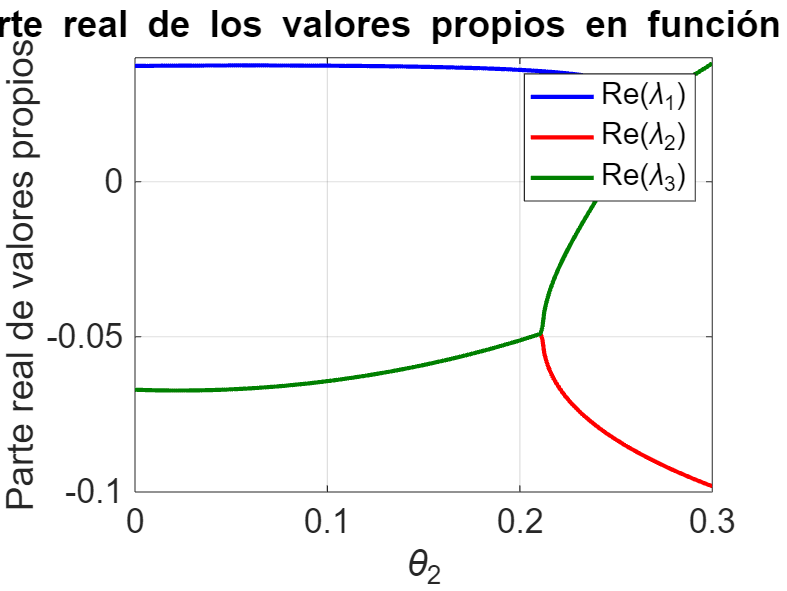

% Limpiar entorno
clear; clc; close all;

% Parámetros simbólicos
syms theta2 x1 x2 x3
assume(theta2 >= 0)

% Parámetros numéricos
alpha1 = 0.00137; beta1 = 0.07; gamma1 = 0.01; mu1 = 0.01;
alpha2 = 0.0011; beta2 = 0.29; gamma2 = 0.01; mu2 = 0.01;
alpha3 = 0.001; beta3 = 0.1; tau = 0.0995; C = 146.9;

% Sistema
f1 = (alpha1 * x1 * (C - x1 - x2 - x3)) / (1 + gamma1 * x3) - x1 * (beta1 + mu1 * x3);
f2 = (alpha2 * x2 * (C - x1 - x2 - x3) * (1 + tau * x1)) / (1 + x3 * gamma2) - x2 * (beta2 + mu2 * x3 - theta2);
f3 = alpha3 * x3 * (C - x1 - x2 - x3) - beta3 * x3;
F = [f1; f2; f3];
vars = [x1, x2, x3];
J = jacobian(F, vars);


sigma1_suma = 1/(2*gamma2*mu2)*( -((beta2-theta2)*gamma2 + mu2) + sqrt( ((beta2-theta2)*gamma2-mu2)^2 + (4*gamma2*mu2*alpha2*beta3)/alpha3 ) );
sigma1_resta = 1/(2*gamma2*mu2)*( -((beta2-theta2)*gamma2 + mu2) - sqrt( ((beta2-theta2)*gamma2-mu2)^2 + (4*gamma2*mu2*alpha2*beta3)/alpha3 ) );
sigma2 = 1/(2*gamma1*mu1)*( -(beta1*gamma1 + mu1) + sqrt( (beta1*gamma1-mu1)^2 + (4*gamma1*mu1*alpha1*beta3)/alpha3 ) );

M = beta2-theta2 + mu2*sigma2;
N = gamma2*sigma2 + 1;
P = alpha2*(beta3/alpha3);

% Definir el valor de punto
punto = "p8";

if punto == "p0"
    x1_formula = 0;
    x2_formula = 0;
    x3_formula = 0;
elseif punto == "p1"
    x1_formula = 0;
    x2_formula = 0;
    x3_formula = C - beta3/alpha3;
elseif punto == "p2"
    x1_formula = 0;
    x2_formula = C - (beta2-theta2)/alpha2;
    x3_formula = 0;
elseif punto == "p3"
    x1_formula = 0;
    x2_formula = C - sigma1_suma - beta3/alpha3;
    x3_formula = sigma1_suma;
elseif punto == "p4"
    x1_formula = 0;
    x2_formula = C - sigma1_resta - beta3/alpha3;
    x3_formula = sigma1_resta;
elseif punto == "p5"
    x1_formula = C - beta1 / alpha1;
    x2_formula = 0;
    x3_formula = 0;
elseif punto == "p6"
    x1_formula = C - sigma2 - beta3/alpha3;
    x2_formula = 0;
    x3_formula = sigma2;
elseif punto == "p7"
    x1_formula = (alpha1*(beta2-theta2)-alpha2*beta1)/(alpha2*beta1*tau);
    x2_formula = C - x1_formula - beta1/alpha1;
    x3_formula = 0;
else
    x1_formula = alpha3*(M*N-P)/(alpha2*tau*beta3);
    x2_formula = C - x1_formula - sigma2 - beta3/alpha3;
    x3_formula = sigma2;
end

% Evaluar Jacobiana 
J_eval = subs(J, [x1, x2, x3], [x1_formula, x2_formula, x3_formula]);

% Valores de theta
theta2_vals = linspace(0, 0.3, 300);
num_thetas2 = length(theta2_vals);
eigenval_matrix = NaN(3, num_thetas2);

% Obtener valores propios en cada theta
for i = 1:num_thetas2
    J_num = double(subs(J_eval, theta2, theta2_vals(i)));
    eigs = eig(J_num);
    eigenval_matrix(:, i) = eigs;
end

% Reordenamiento respetando continuidad
branches = NaN(3, num_thetas2);
branches(:,1) = eigenval_matrix(:,1);

for i = 2:num_thetas2
    prev = branches(:,i-1);
    current = eigenval_matrix(:,i);
    order = zeros(1,3);
    used = false(1,3);
    for j = 1:3
        dists = abs(current - prev(j));
        dists(used) = Inf; % Evitar repetir
        [~, idx] = min(dists);
        order(j) = idx;
        used(idx) = true;
    end
    branches(:,i) = current(order);
end

% Graficar parte real de cada rama
figure;
plot(theta2_vals, real(branches(1,:)), 'b', 'LineWidth', 2); hold on;
plot(theta2_vals, real(branches(2,:)), 'r', 'LineWidth', 2);
plot(theta2_vals, real(branches(3,:)), 'color', [0, 0.5, 0], 'LineWidth', 2);
xlabel('\theta_2'); ylabel('Parte real de valores propios');
title('Parte real de los valores propios en función de \theta_2');
legend('Re(\lambda_1)','Re(\lambda_2)','Re(\lambda_3)');
grid on;

ax = gca;
ax.FontSize = 16;